load("stiffness_matrix_1d.mat","A");
load("load_vector_1d.mat","fh");
len_fh = length(fh);
u0 = rand(len_fh,1);

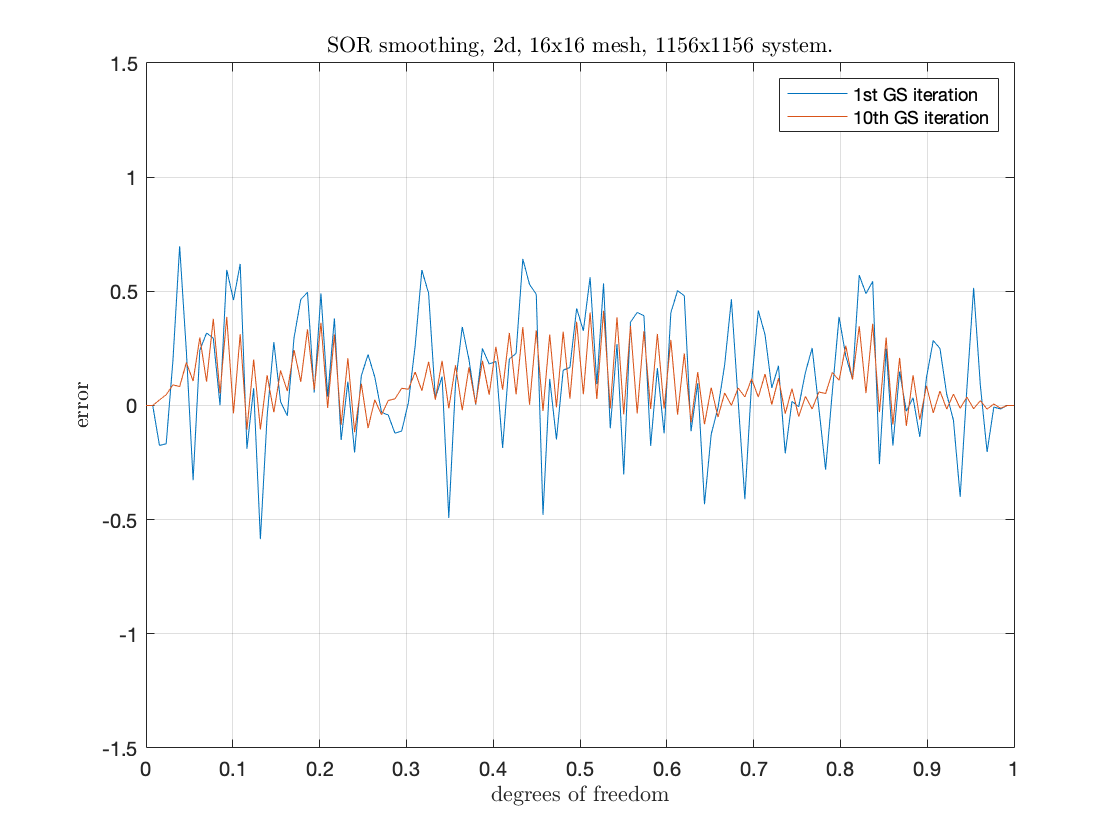

niter = 20;
w = 3/3;
errs = sor(A,fh,w,u0,niter);

xs = 0:1/(len_fh-1):1;

figure
plot(xs, errs(2,:))
hold on
plot(xs, errs(end,:))
hold on
ylim([-1.5,1.5])
title(sprintf("SOR smoothing, 2d, 16x16 mesh, 1156x1156 system."),"Interpreter","latex")
xlabel('degrees of freedom', 'Interpreter',"latex")
ylabel('error', 'Interpreter',"latex")
legend('1st GS iteration', '10th GS iteration')
grid on

function errs = sor(A,f,w,u0,niter)
    u_true = A\f;
    L = tril(A,0);
    U = triu(A,1);
    u = u0;
    errs = zeros(niter+1,length(f));
    errs(1,:) = u-u_true;
    for i=1:niter
        u = (1-w)*u + w*L\(f-U*u);
        errs(i+1,:) = u-u_true;
    end
end